TF_of_interest = 'CTCF';
counts = zeros(64, 1);
current_chr = '';

TF_pos_filename = strcat('factor_pos_separated/factorbookMotifPos.txt');
TFbinding_sites_file = fopen(TF_pos_filename,'rt');

thisline_TF = fgetl(TFbinding_sites_file);

TF_scores = [];
scores = [];

nukes = {'A', 'C', 'G', 'T'};
my_own_TWM_row = repmat([0], 1, TF_binding_length);
my_own_TWM = repmat(my_own_TWM_row, 4, 1)

my_own_TWM =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


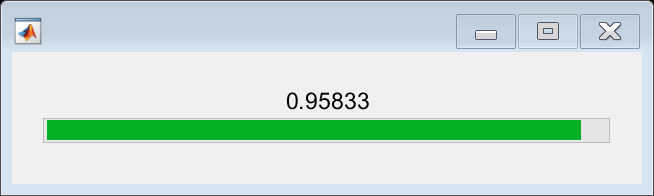

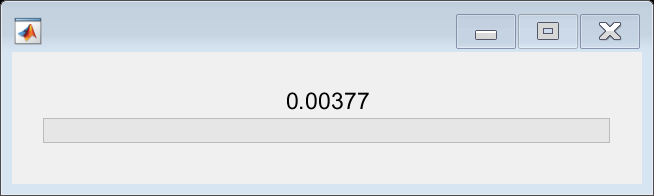

took 13.563155 seconds to read file

took 7.385921 seconds to read file

took 7.231661 seconds to read file

took 7.140858 seconds to read file

took 6.078497 seconds to read file

took 5.624192 seconds to read file

took 5.389866 seconds to read file

took 4.901502 seconds to read file

took 4.427773 seconds to read file

took 4.224371 seconds to read file

took 3.204544 seconds to read file

took 13.448256 seconds to read file

took 3.461945 seconds to read file

took 2.474257 seconds to read file

took 2.585811 seconds to read file

took 10.854838 seconds to read file

took 10.557161 seconds to read file

took 9.857034 seconds to read file

took 9.233456 seconds to read file

took 8.680522 seconds to read file

took 7.881451 seconds to read file

took 7.585030 seconds to read file

took 8.448138 seconds to read file

took 3.180882 seconds to read file

Error using strsplit (line 80)
First input must be either a character vector or a string scalar.



i = 0;
x = 0;
num_TFs = 0;
loading = waitbar(0,'Please wait...');
loading2 = waitbar(0,'Please wait...');

while current_chr ~= "chrY"
% for k=1:1
    r = x/24;
    waitbar(r,loading,string(r));
    x = x+1;
    i = 0;
    
    if ~ischar(thisline_TF); break; end  %end of file

    C = strsplit(thisline_TF,"\t");
    chromosome = C(1,2);
    current_chr = string(chromosome{1});
    
    tic
    filename = strcat('Human Genome/', current_chr, '.fa');
    reads = fastaread(filename);
    current_sequence = reads.Sequence;
    fprintf("took %f seconds to read file", toc)
    current_sequence = upper(string(current_sequence));
    
%     while num_TFs < 20
    while true
        r = i/200000;
        waitbar(r,loading2,string(r));
        i = i+1;
        
        name = C(1,5);
        name = name{1};
        
        if string(name) ~= TF_of_interest
            thisline_TF = fgetl(TFbinding_sites_file);
            C = strsplit(thisline_TF,"\t");
            continue;
        end
        
        num_TFs = num_TFs + 1;
        
        score = C(1,6);
        score = str2double(score{1});
        TF_scores = [TF_scores; score];
        
        strand = C(1,7);
        strand = strand{1};
        start = C(1,3);
        stop = C(1,4);
        start = str2double(start{1});
        stop = str2double(stop{1});
        
        if strand == '+'
            for k = 1:TF_binding_length
                r = extractBetween(current_sequence,start+k,start+k);
                pos = find(nukes == r);
                my_own_TWM(pos, k) = my_own_TWM(pos, k) + 1;
            end
            r = extractBetween(current_sequence,start+1,start+TF_binding_length);
            score =  get_score(0, r, pwm_matrix, TF_binding_length, 1, start_matrix, codons);
            scores = [scores; score];
        
            start_codon = extractBetween(current_sequence,start+1,start+3);
            pos = find(codons == start_codon);
            counts(pos, 1) = counts(pos, 1) + 1;
        else 
            for k = 1:TF_binding_length
                r = extractBetween(current_sequence,start+k,start+k);
                pos = find(nukes == r);
                my_own_TWM(5-pos, TF_binding_length-k+1) = my_own_TWM(5-pos, TF_binding_length-k+1) + 1;
            end
            r = extractBetween(current_sequence,start+1,start+TF_binding_length);
            score = get_score(0, r, pwm_matrix, TF_binding_length, 0, start_matrix, codons);
            scores = [scores; score];
            start_codon = extractBetween(current_sequence,stop - 2,stop);
            start_codon = reverse(start_codon);
            pos = find(codons == start_codon);
            counts(pos, 1) = counts(pos, 1) + 1;
        end

        thisline_TF = fgetl(TFbinding_sites_file);
        if ~ischar(thisline_TF); break; end  %end of file
        C = strsplit(thisline_TF,"\t");
        chromosome = C(1,2);
        if current_chr ~= chromosome{1}
            break;
        end
    end

end


close(loading);
close(loading2);
fclose(TFbinding_sites_file);


i

i = 755

x

x = 24

num_TFs

num_TFs = 158004

my_own_TWM/num_TFs

ans =     0.0744    0.0613    0.1012    0.0556    0.0002    0.2861    0.0083    0.0001    0.0909    0.2279    0.0240    0.1708    0.0153    0.0455    0.1432
    0.3985    0.5299    0.0852    0.7451    0.9839    0.5774    0.6363    0.9959    0.1333    0.1510    0.4628    0.1772    0.0074    0.1427    0.5133
    0.4435    0.0620    0.6230    0.1126    0.0001    0.0569    0.0068    0.0039    0.0244    0.5038    0.4828    0.0872    0.9459    0.7249    0.1410
    0.0836    0.3468    0.1906    0.0866    0.0158    0.0796    0.3486    0.0001    0.7513    0.1173    0.0304    0.5647    0.0314    0.0869    0.2024


real = exp(pwm_matrix) - 0.01

real =     0.0450    0.0150    0.0590    0.0330   -0.0090    0.2530   -0.0050   -0.0090    0.0230    0.2570    0.0110    0.0710    0.0010    0.0170    0.1170
    0.3090    0.6370    0.0330    0.7810    0.9850    0.6570    0.6090    0.9890    0.0550    0.0810    0.3350    0.1850   -0.0070    0.0570    0.5850
    0.5570    0.0150    0.7830    0.0530   -0.0090    0.0370   -0.0070   -0.0070   -0.0010    0.5550    0.6110    0.0350    0.9670    0.8310    0.0650
    0.0530    0.2970    0.0890    0.0970   -0.0030    0.0170    0.3670   -0.0090    0.8870    0.0710    0.0070    0.6730    0.0030    0.0590    0.1970


dif = my_own_TWM - (exp(pwm_matrix) - 0.01);
mean(mean(dif))

ans = 3.9500e+04

std_scores = scores - mean(scores)

std_scores =     2.8148
   -3.4005
   -0.1916
    3.4470
    0.3819
    2.1889
    3.7006
   -0.9508
    2.3911
    0.3819


std_scores = std_scores / std(scores)

std_scores =     1.2705
   -1.5349
   -0.0865
    1.5559
    0.1724
    0.9880
    1.6703
   -0.4292
    1.0793
    0.1724


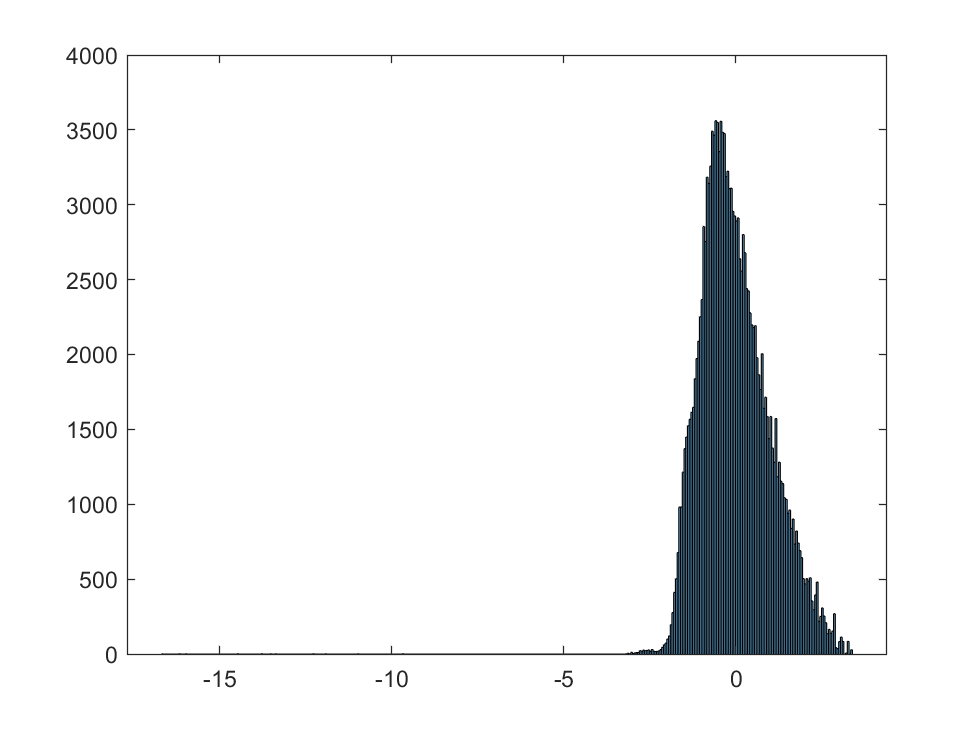

histogram(std_scores)

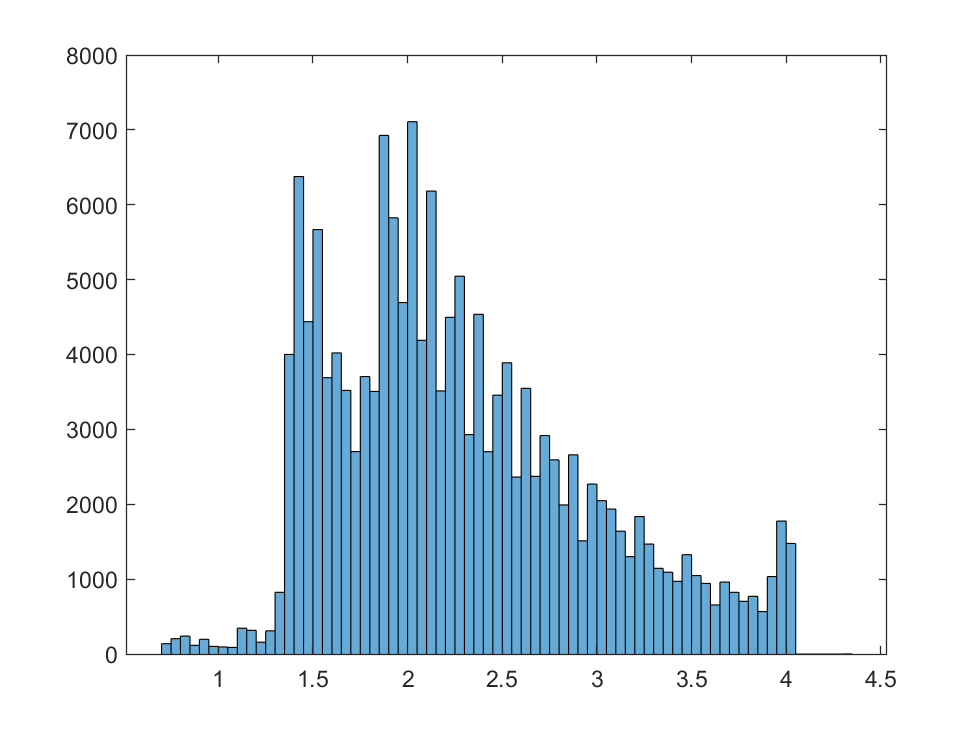

histogram(TF_scores)

scores(1:20)'

ans =   -10.3633  -16.5785  -13.3697   -9.7311  -12.7962  -10.9892   -9.4775  -14.1289  -10.7869  -12.7962  -12.4957   -9.7311  -12.7962   -9.1221   -9.1221   -9.1221  -10.5754  -14.0379  -13.9400  -11.6392


TF_scores(1:20)'

ans =     1.9700    1.4000    2.0700    2.8000    1.9500    2.8300    3.4300    2.2500    3.1500    2.5700    2.9300    3.4500    2.5300    3.2700    3.2700    3.7400    2.5400    2.0200    2.2100    2.8000



score_matrx = [scores(1:20) TF_scores(1:20)]

score_matrx =   -10.3633    1.9700
  -16.5785    1.4000
  -13.3697    2.0700
   -9.7311    2.8000
  -12.7962    1.9500
  -10.9892    2.8300
   -9.4775    3.4300
  -14.1289    2.2500
  -10.7869    3.1500
  -12.7962    2.5700


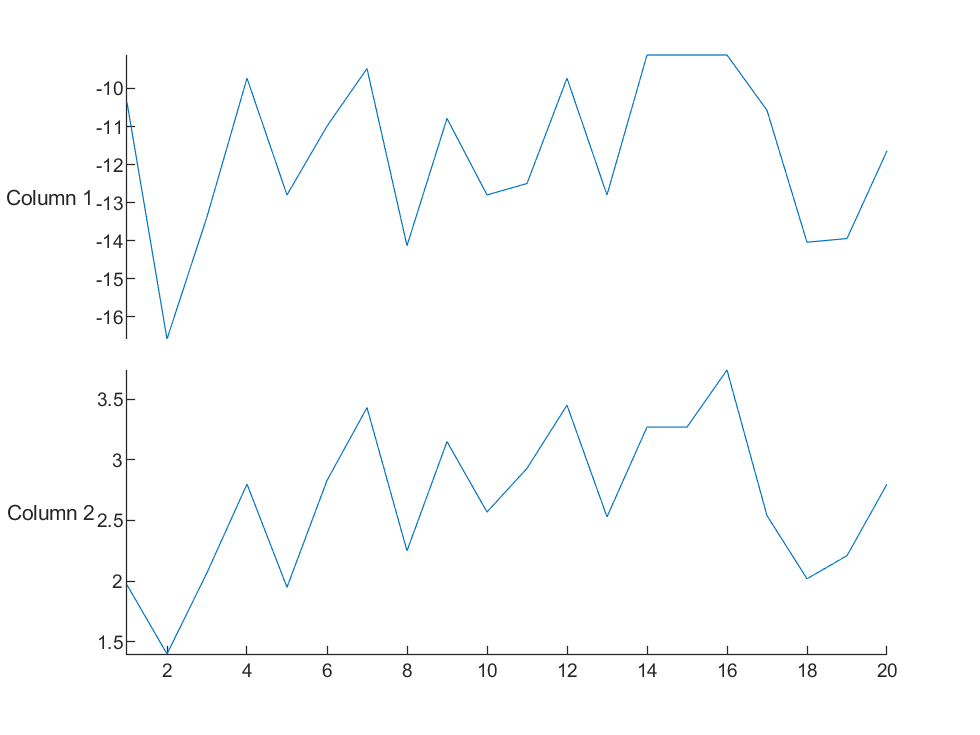


stackedplot(score_matrx)

start_matrix = counts / num_TFs

start_matrix =     0.0021
    0.0095
    0.0025
    0.0006
    0.0036
    0.0058
    0.0080
    0.0059
    0.0081
    0.0096


start_matrix_log = log(start_matrix + 0.0001)

start_matrix_log =    -6.1332
   -4.6421
   -5.9354
   -7.2099
   -5.6008
   -5.1386
   -4.8159
   -5.1226
   -4.8066
   -4.6408


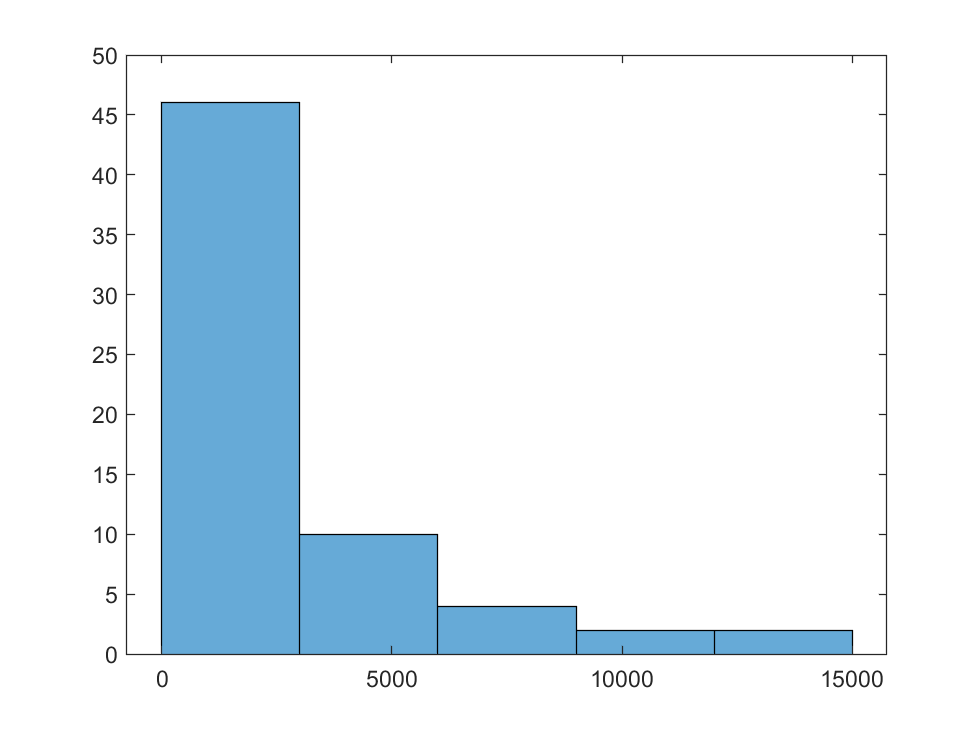

histogram(counts)

[most, idx] = max(counts)

most = 12746

idx = 31

codons(1,idx)

ans = "CTG"

[val, idx] = min(counts)

val = 91

idx = 13

codons(1,idx)

ans = "ATA"

sum(start_matrix)

ans = 1.0000

save("CTCF_logistics", "start_matrix", "start_matrix_log", "counts", "scores", "TF_scores", "num_TFs", "my_own_TWM" )

load("CTCF_logistics")

min(scores)

ans = -50.1133